clear
clc
close all

%% Change directory
% Get the full path of the currently running script
if isdeployed
    % If the code is deployed, use the built-in method
    scriptFullPath = mfilename('fullpath');
else
    % If running in the MATLAB environment, use the editor API
    scriptFullPath = matlab.desktop.editor.getActiveFilename;
end

% Extract the directory part of the path
[scriptDir, ~, ~] = fileparts(scriptFullPath);

% Change the current directory to the script's directory
cd(scriptDir);

% Display the current directory to confirm the change
disp(['Current directory changed to: ', scriptDir]);

Current directory changed to: C:\Users\giaco\Git_Repositories\Semester_Thesis_1\notebooks


% Model fitted coefficients
coeffs = readtable('data/heat_pump/HP_fitted_coefficients.csv');

% Hot side temperature in °C in the data
data25 = readtable('data/heat_pump/temperature25.xlsx');
data50 = readtable('data/heat_pump/temperature50.xlsx');
data75 = readtable('data/heat_pump/temperature75.xlsx');

data = vertcat(data25, data50, data75);

% U_HP = @(DeltaT, I) coeffs.S_M * DeltaT + coeffs.R_M * I;
% P_HP = @(U, I) U .* I;
% Q_c = @(Tc, I, DeltaT) coeffs.S_M * I .* Tc - 0.5 * coeffs.R_M * I.^2 - coeffs.K_M * DeltaT;

curr    = -3:0.5:3;              %A
deltaT  = -80:5:80;             %K
T_hot   = 25; %0:30:60;            %°C
T_hot_K = convtemp(T_hot, 'C', 'K');    %K

curr_str    = string(curr);
deltaT_str  = string(deltaT);
T_hot_str   = string(T_hot);

curr_len    = length(curr_str);
deltaT_len  = length(deltaT_str);
T_hot_len   = length(T_hot_str);

curr_colormap   = flipud(winter(curr_len));
deltaT_colormap = flipud(autumn(deltaT_len));
T_hot_colormap  = flipud(autumn(T_hot_len));

curr_lim = [-3; 3];
deltaT_lim = [-80; 80];
T_hot_lim = [0; 400];
voltage_lim = [-6; 6];
Q_c_lim = [-25; 25];

% Electrical power
label_P_el = "Electrical power / W";

% Dictionary for the labels
headers_keys = data.Properties.VariableNames;
label_values = ["Hot side temperature / K", ...
                "Input voltage / V", ...
                "Temperature difference / K", ...
                "Current / A", ...
                "Heat from cold side / W", ...
                "Heat to hot side / W", ...
                "Coefficient of performance COP / -"];
label_dict = containers.Map(headers_keys, label_values);

% Dictionary for the legends
headers_keys = data.Properties.VariableNames;
legend_values = ["T_h = ", ...
                 "U = ", ...
                 "\Delta_T = ", ...
                 "I = ", ...
                 "Q_{in} = ", ...
                 "Q_{out}", ...
                 "COP = "];
legend_dict = containers.Map(headers_keys, legend_values);

% Dictionary for the units
headers_keys = data.Properties.VariableNames;
units_values = ["°C", ...
                "V", ...
                "°C", ...
                "A", ...
                "W", ...
                "W", ...
                ""];
units_dict = containers.Map(headers_keys, units_values);

# Input Voltage

#### Voltage vs DeltaT 4every Current

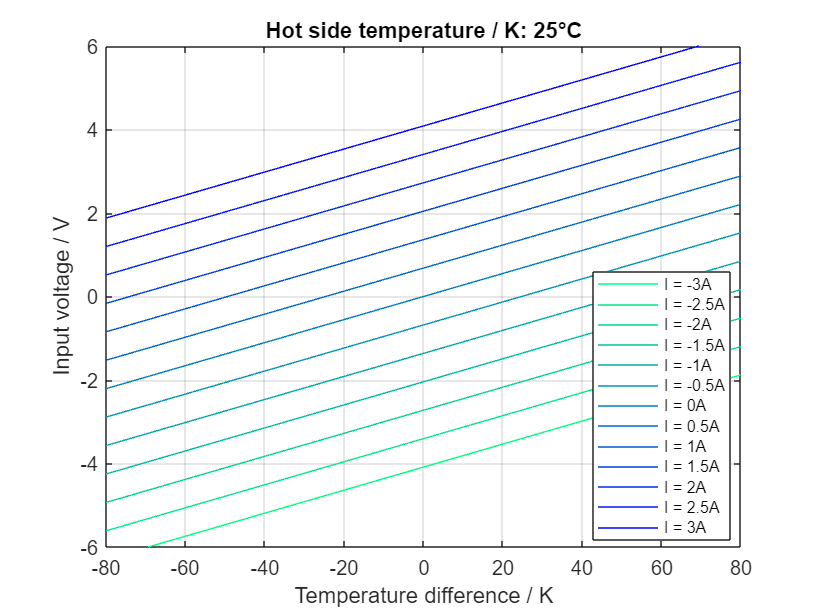

for j = 1:T_hot_len
    figure
    hold on
    
    for i = 1:curr_len
        U = voltage_fct(deltaT, curr(i), coeffs);
    
        p = plot(deltaT, U);
        p.DisplayName = legend_dict(headers_keys{4}) + curr_str(i) + units_dict(headers_keys{4});
        p.Color = curr_colormap(i,:);
    end

    xlabel(label_dict(headers_keys{3}));
    ylabel(label_dict(headers_keys{2}));

    ylim(voltage_lim);
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{1}) + ": " + T_hot_str(j) + units_dict(headers_keys{1}));
    grid on
    box on
    
    hold off
end

# Heat removed from cold side Q_in or Q_c

#### Q_c vs DeltaT 4every Current

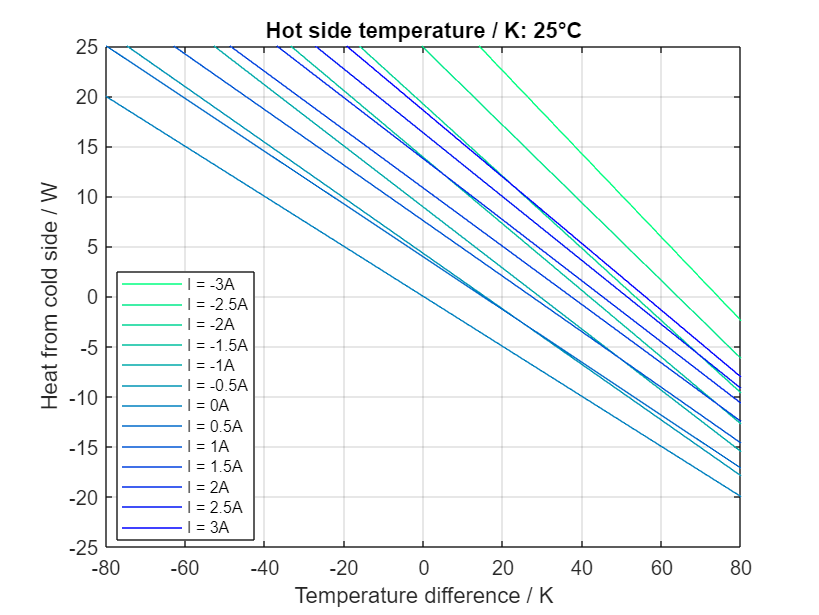

for j = 1:T_hot_len
    figure
    hold on
    
    for i = 1:curr_len
        T_cold = T_hot_K(j) - deltaT;
        Q = heat_removed_fct(T_cold, curr(i), deltaT, coeffs);
    
        p = plot(deltaT, Q);
        p.DisplayName = legend_dict(headers_keys{4}) + curr_str(i) + units_dict(headers_keys{4});
        p.Color = curr_colormap(i,:);
    end

    xlabel(label_dict(headers_keys{3}));
    ylabel(label_dict(headers_keys{5}));

    xlim(deltaT_lim);
    ylim(Q_c_lim);
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{1}) + ": " + T_hot_str(j) + units_dict(headers_keys{1}));
    grid on
    box on
    
    hold off
end

function Q_c = heat_removed_fct(Tc, I, DeltaT, coeffs)
    if I >= 0
        Q_c = coeffs.S_M * I .* Tc - 0.5 * coeffs.R_M * I.^2 - coeffs.K_M * DeltaT;
    else
        Q_c = - coeffs.S_M * I .* Tc - 0.5 * coeffs.R_M * I.^2 - coeffs.K_M * DeltaT + power_fct(voltage_fct(DeltaT, I, coeffs), I);
    end
end

function U_HP = voltage_fct(DeltaT, I, coeffs)
    U_HP = coeffs.S_M * DeltaT + coeffs.R_M * I;
end

function P_HP = power_fct(U, I)
    P_HP = U .* I;
end